## Clear the data

close
clear
clc

## Orientation distance reference

generate the frame

gridSize = 0.05;
nDirection = 10;
nRotation = 3;

[xDir, yDir, zDir] = saffAndKuijlaars(gridSize, nDirection);
tform = repmat(eye(4,4), 1, 1, nDirection, nRotation);
for iDirection = 1:nDirection
    tform(1,4,iDirection,:) = xDir(iDirection);
    tform(2,4,iDirection,:) = yDir(iDirection);
    tform(3,4,iDirection,:) = zDir(iDirection);
    position = [xDir(iDirection); yDir(iDirection); zDir(iDirection)];

    % calculate the initial rotation matrix
    Rz = - position/norm(position);
    Rx = zeros(3,1);
    Rx(3) = norm([Rz(1),Rz(2)]);
    if abs(Rx(3)) < eps
        Rx(1) = 1;
        Rx(2) = 0;
    else
        if Rz(3) < 0
            Rx(1) = abs(Rz(3)) / Rx(3) * Rz(1);
            Rx(2) = abs(Rz(3)) / Rx(3) * Rz(2);
        else
            Rx(1) = - abs(Rz(3)) / Rx(3) * Rz(1);
            Rx(2) = - abs(Rz(3)) / Rx(3) * Rz(2);
        end
    end
    Ry = cross(Rz, Rx);
    R = [Rx,Ry,Rz];

    rotationScalar = linspace(0, 2*pi, nRotation+1);
    for iRotation = 1:nRotation
        iR = axang2rotm([Rz',rotationScalar(iRotation)])*R;
        tform(1:3,1:3,iDirection,iRotation) = iR;
    end
end

gridOrientation = tform;
size(gridOrientation);

calculate the norm(log) between these frames

progressbar = ProgressbarCollection();
progressbar.setProgressMaximum(1, nDirection*nRotation*nDirection*nRotation, 'logDist');
parStep = progressbar.parallelStepHandle();

logDist = zeros(nDirection*nRotation, nDirection*nRotation);
for iDir1 = 1:nDirection
    for iRot1 = 1:nRotation
        index1 = (iDir1-1)*3+iRot1;
        for iDir2 = 1:nDirection
            for iRot2 = 1:nRotation
                index2 = (iDir2-1)*3+iRot2;
                logDist(index1,index2) = norm(logmapR(gridOrientation(1:3,1:3,iDir2,iRot2)'*gridOrientation(1:3,1:3,iDir1,iRot1)));
                send(parStep, 1);
            end
        end
    end
end
progressbar.finishProgress(1);
delete(progressbar);

visualize the result

logDist

logDist =          0    8.3776    8.3776    4.3125   11.8372    5.5710    7.8144   10.0413    4.1232   11.2982    7.2689    5.5018   10.5252    5.9780    8.5505    7.9842    7.3461   12.0441    7.6586   10.5439    9.9134   10.2788   11.0691    8.6689   11.1286    9.8502   11.3272    6.2832   16.6237   16.6237
    8.3776         0    8.3776    5.5710    4.3125   11.8372    4.1232    7.8144   10.0413    5.5018   11.2982    7.2689    8.5505   10.5252    5.9780   12.0441    7.9842    7.3461    9.9134    7.6586   10.5439    8.6689   10.2788   11.0691   11.3272   11.1286    9.8502    6.2832    6.2832   12.5664
    8.3776    8.3776         0   11.8372    5.5710    4.3125   10.0413    4.1232    7.8144    7.2689    5.5018   11.2982    5.9780    8.5505   10.5252    7.3461   12.0441    7.9842   10.5439    9.9134    7.6586   11.0691    8.6689   10.2788    9.8502   11.3272   11.1286    6.2832   12.5664    6.2832
    4.3125    5.5710   11.8372         0    8.3776    8.3776    3.8324   11.0668    6.3

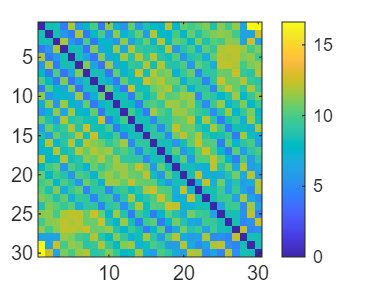

imagesc(logDist)
colorbar

## Nullspace vector